genealogicalTreePlot_ArcTest

shuai Yang 2020.05.11

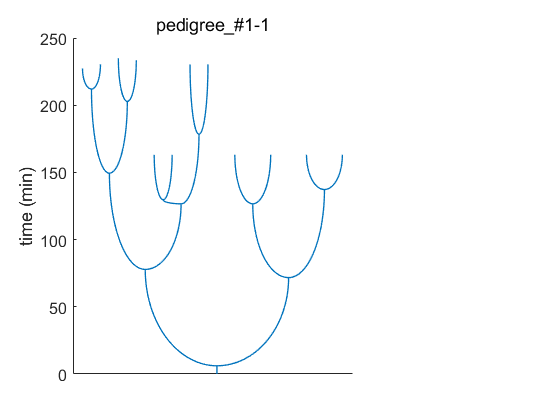

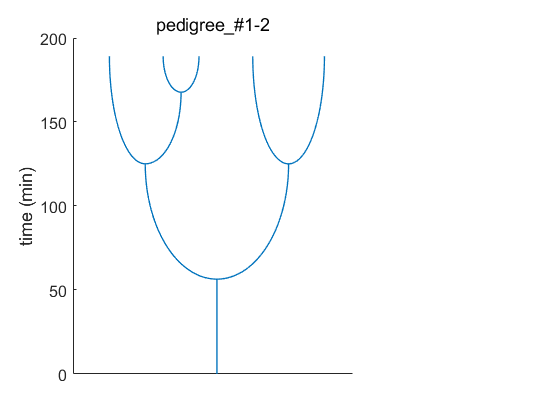

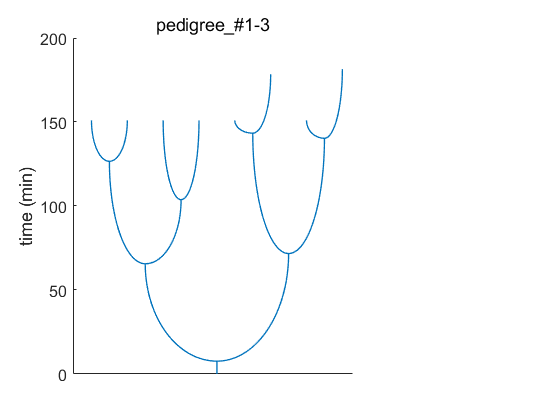

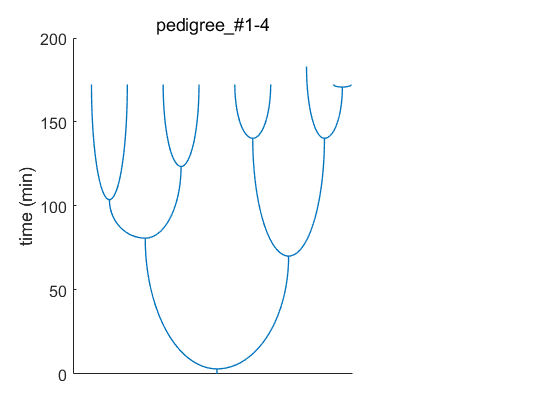

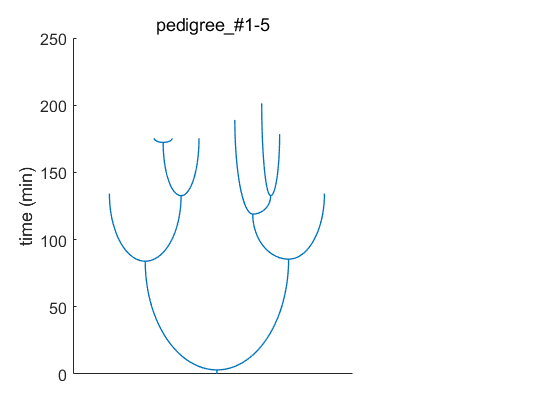

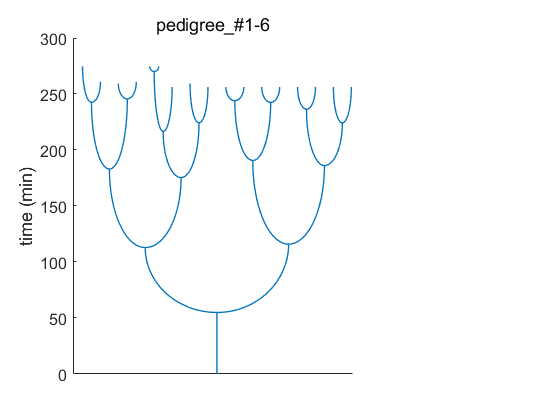

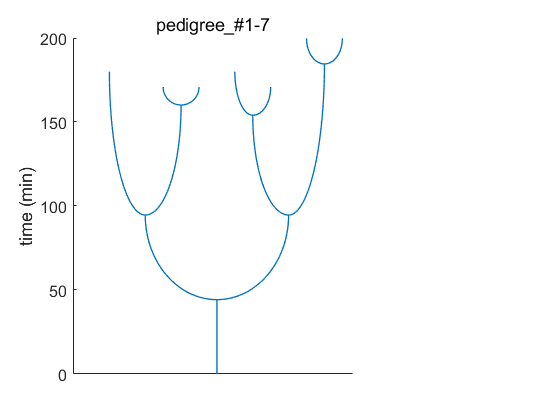

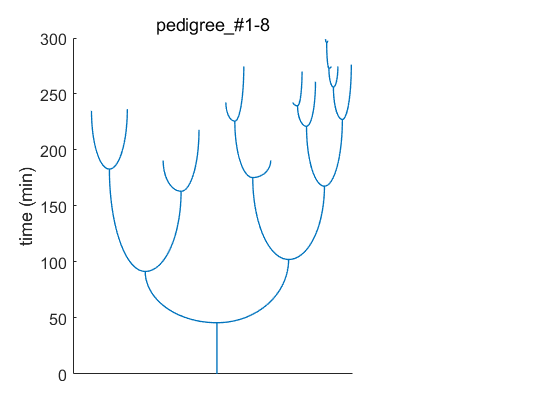

%x位置进行自己定义，y为时间，用1/4椭圆的弧线连接生成genealogicalTree

% shuai Yang 2020.05.11
labelPos = cellXpositonAllocation;

for i = 1:numel(pedigreeAll)
    [leafLabels] = leafLabelsGeneration(pedigreeAll,i);
    fname = strcat('pedigree_#',num2str(pedigreeAll(i).frameIdx),'-',num2str(pedigreeAll(i).rootIdx));
    
    
    for iLeaf = 1:pedigreeAll(i).leafNum
        if pedigreeAll(i).tree(iLeaf).label==1 % 如果label等于1 root标签
            
            cellLabel = pedigreeAll(i).tree(iLeaf).label;
            arcEnds = zeros(2,2);
            arcEnds(:,1) = labelPos(cellLabel,2);%x position
            arcEnds(1,2) = pedigreeAll(i).tree(iLeaf).timer(1);%y  time
            arcEnds(2,2) = pedigreeAll(i).tree(iLeaf).timer(end);%y  time
            arcLinkPts = arcEnds;
            
        else
            %不等于1，arcPts先确定长短轴的两个点 
            cellLabel = pedigreeAll(i).tree(iLeaf).label;
            arcEnds = zeros(2,2);
            arcEnds(2,1) = labelPos(cellLabel,2);%x position
            arcEnds(2,2) = pedigreeAll(i).tree(iLeaf).timer(end);%ytime
            
            motherLabel = fix(pedigreeAll(i).tree(iLeaf).label/2);%找到其母代细菌的label
            posIdx = find(leafLabels == motherLabel);%根据label找位置
            arcEnds(1,:) = pedigreeAll(i).tree(posIdx).arcEnds(end,:);
%             [arcLinkPts] = linkTwoPtsWithQuarterEllipse(arcEnds);
            [arcLinkPts] = linkTwoPtsWithQuarterEllipseNew(arcEnds);
            
            
        end
        
        pedigreeAll(i).tree(iLeaf).arcEnds =arcEnds;
        pedigreeAll(i).tree(iLeaf).arcLinkPts =arcLinkPts;
    end
    
    treePlot_arcLink(i,fname,pedigreeAll)
end

%subfunction

function [leafLabels] = leafLabelsGeneration(pedigreeAll,i)
leafLabels = zeros(pedigreeAll(i).leafNum,1);
for iLeaf = 1:pedigreeAll(i).leafNum
    leafLabels(iLeaf)=pedigreeAll(i).tree(iLeaf).label;
end

end 

% label与xpositon分配

%按最多分裂九代 最终共256个细菌，

%第八代的label为256-511

%第八代的label为128-255，第七代为64-127

%第六代的label为32-63，第五代为16-31

%第四代的label为8-15，第三代为4-7

%第二代的label为2-3，第一代为1

function labelPos = cellXpositonAllocation()
%g 为代数 分配位置2^g-1;细菌数目2^(g-1)个
%第一列为label的数字
%第二列为给分配的x位置
g=9;
labelPos = zeros (2^g-1,2);
labelPos(:,1) = 1:2^g-1;
%先给256-511分配位置为[1,256]
labelPos(2^(g-1):2^g-1,2) = 1 :2^(g-1);

%给剩下的1-255 分配位置,255为510和511的中间值
for i = 2^(g-1)-1 :-1:1
    labelPos(i,2) = (labelPos(i*2,2)+labelPos(i*2+1,2))/2;
end

end

%two points connect with arc 1/4 ellipse

function [arcLinkPts] = linkTwoPtsWithQuarterEllipse(arcEnds)

% 椭圆的中心点 1st pt的x位置; 2nd pt的y位置
% Ellipse function (x-x0)^2/a^2+(y-y0)^2/b^2 == 1
%syms  x y x0 y0 a b
%eqn = ((x-x0)^2)/(a^2)+((y-y0)^2)/(b^2) == 1

x0 = arcEnds(1,1);y0 = arcEnds(2,2);
a = abs(arcEnds(1,1)-arcEnds(2,1));% a = |x1-x2|
b = abs(arcEnds(1,2)-arcEnds(2,2));% b = |y1-y2|



nbin =200;
arcLinkPts =zeros(nbin,2);

% %平分x，计算y；
% xbin = linspace(arcPts(1,1),arcPts(2,1),nbin);
% ybin = zeros(1,nbin);
% 
% % y的两个解 取比y0小的数
% % %Sy = solve(eqn,y)
% f = @(x) y0 - (b*(a + x - x0)^(1/2)*(a - x + x0)^(1/2))/a; 
% for i =1:nbin
%     ybin(i) =f(xbin(i));
% end
% linkPts(:,1) = xbin;
% linkPts(:,2) = ybin;

% %平分y，计算x；
xbin = zeros(1,nbin);
ybin = linspace(arcEnds(1,2),arcEnds(2,2),nbin);
%Sx = solve(eqn,x);
if arcEnds(1,1) > arcEnds(2,1)
    f = @(y) x0 - (a*(b + y - y0)^(1/2)*(b - y + y0)^(1/2))/b; 
else
    f = @(y) x0 + (a*(b + y - y0)^(1/2)*(b - y + y0)^(1/2))/b; 
end

for i =1:nbin
    xbin(i) =f(ybin(i));
end
arcLinkPts(:,1) = xbin;
arcLinkPts(:,2) = ybin;

end

%two points connect with arc 1/4 ellipse %不平分x或y 平分角度`angle`

function [arcLinkPts] = linkTwoPtsWithQuarterEllipseNew(arcEnds)

% 椭圆的中心点 1st pt的x位置; 2nd pt的y位置
% Ellipse function x = x0+a*cos(rad_ang);y = y0+a*sin(rad_ang)


x0 = arcEnds(1,1);y0 = arcEnds(2,2);
a = abs(arcEnds(1,1)-arcEnds(2,1));% a = |x1-x2|
b = abs(arcEnds(1,2)-arcEnds(2,2));% b = |y1-y2|

nbin =90;

f = @(rad_ang)  [x0 + a*cos(rad_ang); y0 + b*sin(rad_ang)];  

if arcEnds(1,1) > arcEnds(2,1)
    r_angl = linspace(pi, 3*pi/2, nbin);   
else
    r_angl = linspace(3*pi/2, 2*pi, nbin);   
end


arcLinkPts = f(r_angl); 
arcLinkPts = arcLinkPts';
end

%plot function

function treePlot_arcLink(i,fname,pedigreeAll)

% close all
figure,
f1 = figure('Name',fname);
% set(f1,'visible','off')
axes1 = axes('Parent',f1,'Position',[0.13 0.11 0.5 0.8]);
% hold(axes1,'on');
for iLeaf = 1:pedigreeAll(i).leafNum
    arcLinkPts = pedigreeAll(i).tree(iLeaf).arcLinkPts;
    line(arcLinkPts(:,1),arcLinkPts(:,2),'Color',[0,0.45,0.74],'LineWidth',1)
    hold on
end
ylabel({'time (min)'});
title(fname,'Interpreter','none');

% hold(axes1,'off')
hold off
set(axes1,'FontSize',12,'XTick',zeros(1,0));

% saveas(f1,[dirSave,'\',fname,'.fig'])


end